clc; clear; close all
cd 'G:\Jiaxu Flashdrive Backup\GPR model'
addpath 'G:\Jiaxu Flashdrive Backup\code\functions'

imds = imageDatastore("G:\Jiaxu Song\DL images\GPR model test\test16_down");

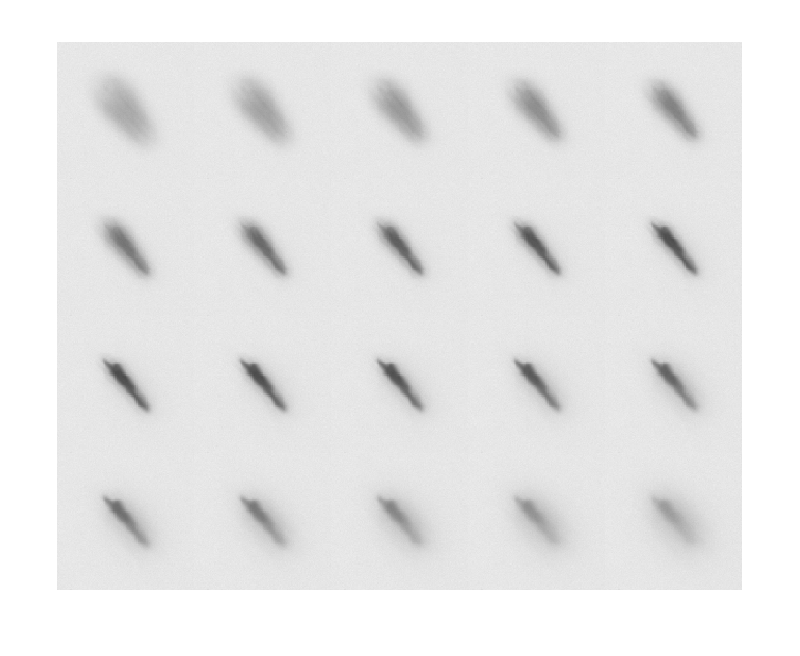

for i = 1:length(imds.Files)
    I(:,:,i) = readimage(imds,i);
end
imshow(I(:,:,1));
[x,y] = ginput(1);
close all
x = round(x); y = round(y);
for i = 1:length(imds.Files)
    image_of_interested(:,:,i) = chopimage(I(:,:,i),x,y);
end
montage(image_of_interested);

[filepath,name,ext] = fileparts(imds.Files);
height = regexp(name,'\d*','Match');
height = height';
for i = 1:length(imds.Files)
b = height{i};
height_out(i) = cellfun(@str2num,b)/10;
end
height_out = height_out';

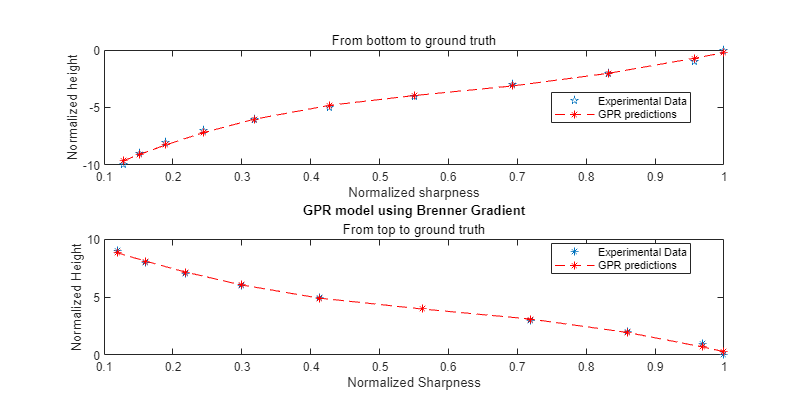

for i = 1:length(imds.Files)
    bren_sharp(i) = brenner(image_of_interested(:,:,i));
end
max_bren = max(max(bren_sharp));
[~,b_num] = find(bren_sharp == max_bren);
max_sharp_h = height_out(b_num);
norm_height_b = height_out - max_sharp_h;
norm_sharp_b = norm_array(bren_sharp,"brenner");

bren_sharp_top = norm_sharp_b(1:b_num);
bren_sharp_bot = norm_sharp_b(b_num:end);
norm_height_b_top = norm_height_b(1:b_num);
norm_height_b_bot = norm_height_b(b_num:end);

sigma0 = 0.5;
kparams0 = [3.5, 6.2];

gprMd_bau_top = fitrgp(bren_sharp_top',norm_height_b_top);
gprMd_bau_bot= fitrgp(bren_sharp_bot',norm_height_b_bot');

bre_pred_top = resubPredict(gprMd_bau_top);
bre_pred_bot = resubPredict(gprMd_bau_bot);

subplot(2,1,1)
plot(bren_sharp_top,norm_height_b_top,'p'); hold on
plot(bren_sharp_top,bre_pred_top,'--*r'); hold off;
subtitle('From bottom to ground truth')
legend('Experimental Data','GPR predictions','Location', 'Best');
xlabel('Normalized sharpness'); ylabel('Normalized height')
subplot(2,1,2)
plot(bren_sharp_bot,norm_height_b_bot,'*'); hold on
plot(bren_sharp_bot,bre_pred_bot,'--*r'); hold off;
subtitle('From top to ground truth')
title('GPR model using Brenner Gradient')
legend('Experimental Data','GPR predictions','Location', 'Best');
xlabel('Normalized Sharpness'); ylabel('Normalized Height')

x0=0; y0=0;
width=800;
height=400;
set(gcf,'position',[x0,y0,width,height])

% set(gca,'xticklabel',norm_height_b)

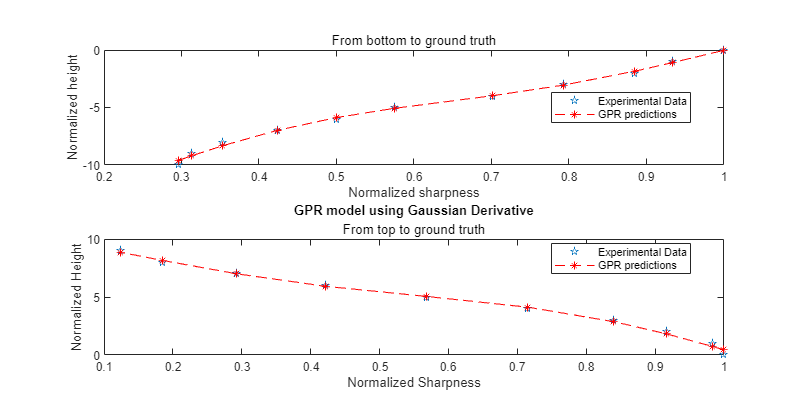

for i = 1:length(imds.Files)
    norm_img(:,:,i) = normlize_image(image_of_interested(:,:,i),255);
    w = 8;
    gau_sharp(i) = Gaussian_derivative(norm_img(:,:,i),w);
end
max_gau = max(max(gau_sharp));
[~,g_num] = find(gau_sharp == max_gau);
max_gau_sharp_h = height_out(g_num);
norm_height_g = height_out - max_gau_sharp_h;
norm_gau_sharp = norm_array(gau_sharp,"gaussian");

gau_sharp_top = norm_gau_sharp(1:g_num);
gau_sharp_bot = norm_gau_sharp(g_num:end);
norm_height_g_top = norm_height_g(1:g_num);
norm_height_g_bot = norm_height_g(g_num:end);


gprMd_gau_top = fitrgp(gau_sharp_top',norm_height_g_top');
gprMd_gau_bot= fitrgp(gau_sharp_bot',norm_height_g_bot');


gau_pred_top = resubPredict(gprMd_gau_top);
gau_pred_bot = resubPredict(gprMd_gau_bot);

subplot(2,1,1)
plot(gau_sharp_top,norm_height_g_top,'p'); hold on;
plot(gau_sharp_top,gau_pred_top,'--*r'); hold off;
subtitle('From bottom to ground truth')
xlabel('Normalized sharpness'); ylabel('Normalized height')
legend('Experimental Data','GPR predictions','Location','Best');


subplot(2,1,2)
plot(gau_sharp_bot,norm_height_g_bot,'p'); hold on;
plot(gau_sharp_bot,gau_pred_bot,'--*r'); hold off;
subtitle('From top to ground truth')
xlabel('Normalized Sharpness'); ylabel('Normalized Height')
legend('Experimental Data','GPR predictions','Location','Best');
title('GPR model using Gaussian Derivative')

x0=0; y0=0;
width=800;
height=400;
set(gcf,'position',[x0,y0,width,height])
% set(gca,'xticklabel',norm_height_g)

%saveimgtofile(image_of_interested,12,"G:\\GPR model\\gpr test images\\brenner gpr test\\test12\\%d_%d.png")